***Integrantes***:

- Naysla tatiana torres Cortes

- Ariel David Herrera Ahumda

# Metodo Larange

Considerando que los siguientes datos son suministrados por grupo de profesionales que requieren determinar la temperatura de ebullición de una determinada sustancia a diferentes presiones, se les solicita hallar:

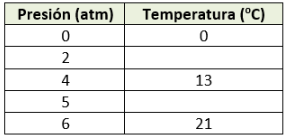

## Fórmulas

Hallar por medio de interacciones

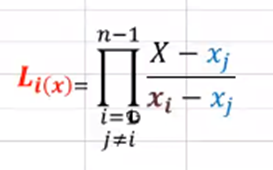

Hallar por medio de interacciones

%ingresar los puntos a evaluar
x=[0 4 6]

x =      0     4     6


f=[0 13 21]

f =      0    13    21


ans = 'sub polinomios_1'

$$L = 1-\frac{t}{4}$$

ans = 'sub polinomios_1'

$$L = \frac{\left(\frac{t}{4}-1\right)\,\left(t-6\right)}{6}$$

ans = '----------'

$$p = 0$$

ans = 'sub polinomios_2'

$$L = \frac{t}{4}$$

ans = 'sub polinomios_2'

$$L = -\frac{t\,\left(t-6\right)}{8}$$

ans = '----------'

$$p = -\frac{13\,t\,\left(t-6\right)}{8}$$

ans = 'sub polinomios_3'

$$L = \frac{t}{6}$$

ans = 'sub polinomios_3'

$$L = \frac{t\,\left(t-4\right)}{12}$$

ans = '----------'

$$p = \frac{7\,t\,\left(t-4\right)}{4}-\frac{13\,t\,\left(t-6\right)}{8}$$

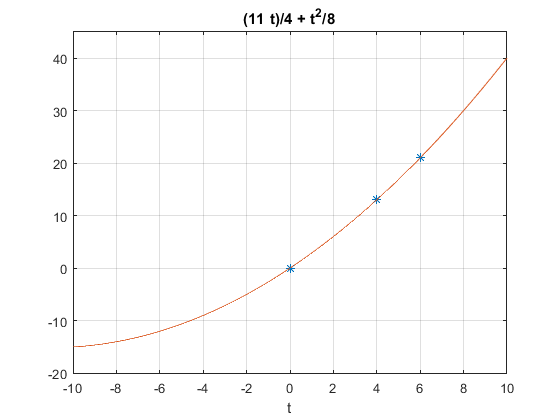

$$ans = \frac{t^{2}}{8}+\frac{11\,t}{4}$$

interpolacionLagrange(x,f)

strcat('evaluando la funcion en puntos específicos')

ans = 'evaluando la funcion en puntos específicos'

a=2;
strcat('punto_',num2str(a))

ans = 'punto_2'

interpolacionLagrange2(x,f,a)

ans = 6

a=5;
strcat('punto_',num2str(a))

ans = 'punto_5'

interpolacionLagrange2(x,f,a)

ans = 16.8750

## Funciones

function [p]=interpolacionLagrange(x,f)
    %x absisas (x)
    %f ordenadas (y) 
    n=length(x); %tamaño de los vectores
    syms t; %variable simbólica
    p=0;
    plot(x,f,'*')%para graficar
    grid on; %mallado
    %iteraciones
    for i=1:n
        L=1; %inicia en uno para que el producto no inicie en 0
        for j=1:n
            %vaidar si j es diferente de i
            ps=0;
            if i~=j
                strcat('sub polinomios_',num2str(i))
                L=L*(t-x(j))/(x(i)-x(j))
                %strcat('sub polinomios_',num2str(i))
               % ps=ps+L 
            end                        
        end         
        % f(i) es el y(i) 
        strcat('----------')
        p=p+L*f(i)
    end
     %polinomio simplificado
    p=expand(p);
    hold on;
    ezplot(p,[-10,10])
end

%Evaluar en un punto específico la función
function [p]=interpolacionLagrange2(x,f,a)
    %x absisas
    %f ordenadas 
    %a un punto sobre el que se evalua la funcion
    n=length(x); %tamaño de los vectores
    syms t; %variable simbólica
    p=0;
    %plot(x,f,'*')%para graficar
    %grid on; %mallado
    %iteraciones
    for i=1:n
        L=1; %inicia en uno para que el producto no inicie en 0
        for j=1:n
            %vaidar si j es diferente de i
            if i~=j
                L=L*(t-x(j))/(x(i)-x(j));
            end
        end 
        % f(i) es el y(i)
        p=p+L*f(i);   
    end
    %p=expand(p);
    %hold on;
    %ezplot(p,[0,10])
    t=a;
    p=eval(p);
end